# RobotX Hand Calculations

close all
clear
clc

filename = 'Acceleration without g 2024-06-22 09-59-25.xls - Raw Data.csv';
raw_data = readtable('Raw_Data.csv');

data = readtable(filename);

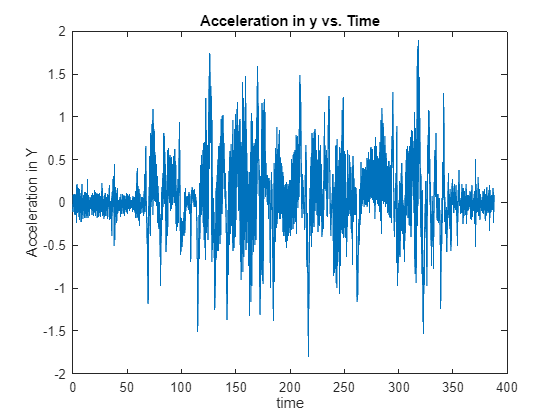

acc_y = data.LinearAccelerationY_m_s_2_;
time = data.Time_s_;
plot(time,acc_y)
title('Acceleration in y vs. Time')
xlabel('time');
ylabel('Acceleration in Y');


max_acc = max(abs(acc_y));
[m,n] = find(acc_y == max(abs(acc_y)));
time_of_max_acc = time(m,n);
v0 = 0;

% max_vel = v0 + max_acc * time_of_max_acc;

first_index = 31704;
last_index = 31732;

delta_time = time(last_index) - time(first_index);

max_vel = v0 + max_acc * delta_time;

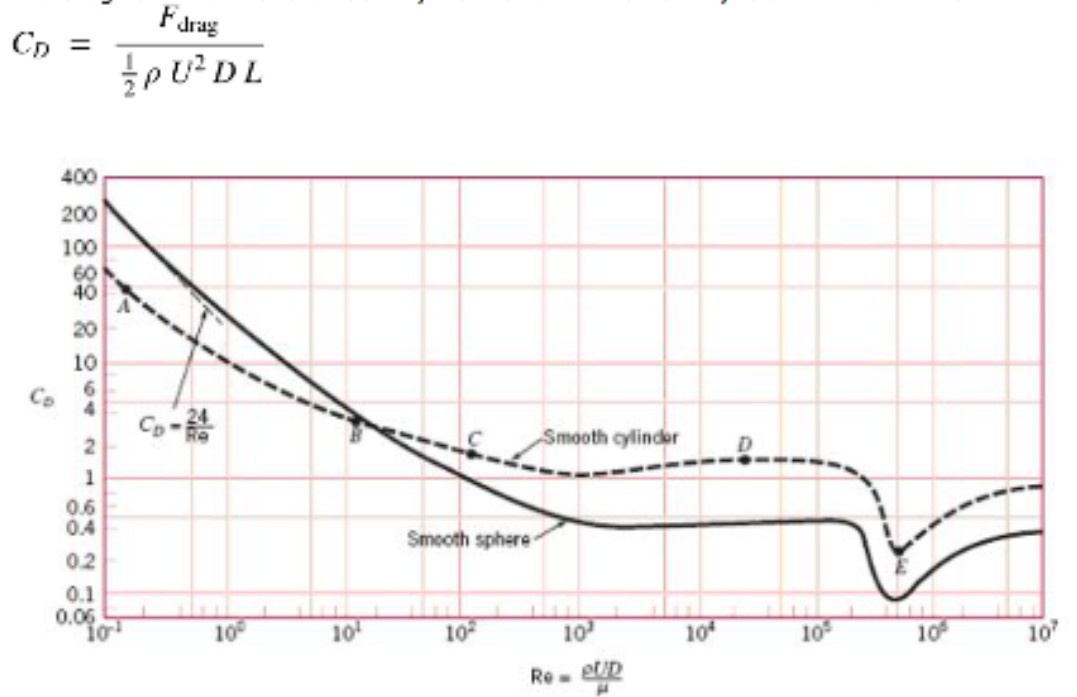

## Check average Velocity

% Preallocate
vel = zeros(length(acc_y), 1);
for n = 2:length(acc_y)
    dt = time(n) - time(n-1);
    % Use trapezoidal method to find mean
    vel(n) = vel(n-1) + 0.5*(acc_y(n)+acc_y(n-1))*dt;
    % 0.5*(acc_y(n)+acc_y(n-1)) is the average acceleration
end

mean_vel = mean(vel);

## Calculate Drag Force

D = 0.033401; % (m)
L = 0.6096; % (m)
h2o_density = 998.2; % (kg/m^3)
h2o_kinematic_viscosity = 1.004*10^(-6); % (m^2/s)
h2o_dynamic_viscosity = 1.002*10^(-2);
reynold_num = 0.5319*0.033401/(1.004*10^-6);
Cd = 2;

Fd = 0.5*Cd*D*L*h2o_density*(mean_vel^2);

## Impact form Horizontally Moving Object

% Work = Kinetic_Energy = Force*distance = 0.5*mass*velocity^2
% Going to use the average velocity
% Force = 0.5*mass*mean_vel^2/distance
% Distance: 1-3 ft
distance = 0.3048 % [m];

distance = 0.3048

mass = 222.26 % [kg];

mass = 222.2600

Force = 0.5*mass*mean_vel^2/distance;